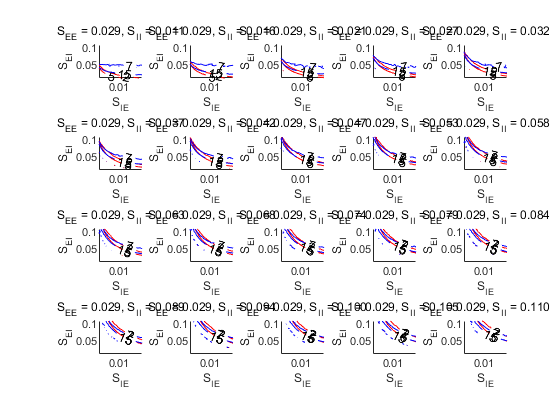

load('ContourData_S_EE=0.029_3D.mat','ContourData_3D')


figure(1)
for S_IIInd = 1:length(ContourData_3D.S_IItest)
    subplot(4,5,S_IIInd)
    hold on
    CurrentFrE = squeeze(ContourData_3D.Fr_NoFix(1,:,:,S_IIInd)); CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_3D.Fr_NoFix(2,:,:,S_IIInd)); CurrentFrI(CurrentFrI<eps) = nan;
    [C1,h1]= contour(ContourData_3D.S_IEtest,ContourData_3D.S_EItest,...
                     CurrentFrE,[2 5],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_3D.S_IEtest,ContourData_3D.S_EItest,...
                     CurrentFrI,[7 15],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    hold off
    S_IItxt = sprintf('%.3f',ContourData_3D.S_IItest(S_IIInd));
    title(['S_{EE} = 0.029, S_{II} = ' S_IItxt ])
    xlabel('S_{IE}');ylabel('S_{EI}')
end

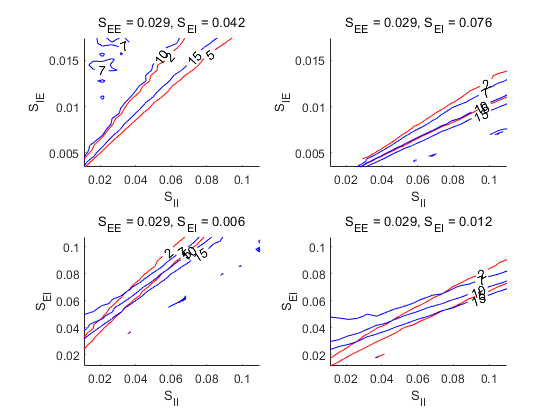

figure(2)
S_EIInd = [11,22];
S_IEInd = [5 15];

% fix S_EI, change S_IE
for plotInd = 1:2
    ei = S_EIInd(plotInd);
    subplot(2,2,plotInd)
    hold on
    CurrentFrE = squeeze(ContourData_3D.Fr_NoFix(1,ei,:,:)); CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_3D.Fr_NoFix(2,ei,:,:)); CurrentFrI(CurrentFrI<eps) = nan;
%     CurrentFrE = permute(CurrentFrE,[2 1]);
%     CurrentFrI = permute(CurrentFrI,[2 1]); % S_II first, so it will be on y axis
    [C1,h1]= contour(ContourData_3D.S_IItest,ContourData_3D.S_IEtest,...
                     CurrentFrE,[2 5],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_3D.S_IItest,ContourData_3D.S_IEtest,...
                     CurrentFrI,[7 10 15],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    
        hold off
    S_EItxt = sprintf('%.3f',ContourData_3D.S_EItest(ei));
    title(['S_{EE} = 0.029, S_{EI} = ' S_EItxt ])
    xlabel('S_{II}');ylabel('S_{IE}')
end

% fix S_IE, change S_EI
for plotInd = 1:2
    ie = S_IEInd(plotInd);
    subplot(2,2,2+plotInd)
    hold on
    CurrentFrE = squeeze(ContourData_3D.Fr_NoFix(1,:,ie,:)); CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_3D.Fr_NoFix(2,:,ie,:)); CurrentFrI(CurrentFrI<eps) = nan;
%     CurrentFrE = permute(CurrentFrE,[2 1]);
%     CurrentFrI = permute(CurrentFrI,[2 1]); % S_II first, so it will be on y axis
    [C1,h1]= contour(ContourData_3D.S_IItest,ContourData_3D.S_EItest,...
                     CurrentFrE,[2 5],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_3D.S_IItest,ContourData_3D.S_EItest,...
                     CurrentFrI,[7 10 15],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    
        hold off
    S_IEtxt = sprintf('%.3f',ContourData_3D.S_IEtest(ie));
    title(['S_{EE} = 0.029, S_{EI} = ' S_IEtxt ])
    xlabel('S_{II}');ylabel('S_{EI}')
end